# Viewing Single Image Channel of Image Datacube

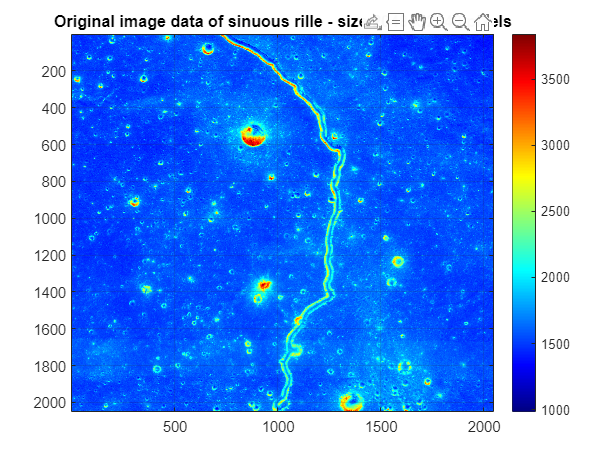

prompt = "Please enter the path to image data you want to visualise.";
filename = input(prompt, "s");
%filename = "C:\Patches\OrbitalDataExplorerData\AllImages\mi_map_03_n17e310n16e311sc.img";
global patchSize
global currentCombination
global chnr

%% MI data

bandnr = 2:10;
chnr = 9; % write the number of vis-nir channels we want to arbitrarily select
vis_nir_combs = nchoosek(bandnr, chnr);
for i = height(vis_nir_combs)
    currentCombination = [1 vis_nir_combs(i,:)];
end

%% RGB data

% currentCombination = [1, 5, 10];
% chnr = length(currentCombination);

patchSize = 2048; % change based on patch size of image data chosen

% Image1 = readPatchWithProcessing(filename);
Image2 = readPatch(filename);

% tiledlayout(4,2)
% nexttile
% imagesc(Image1(:,:,1))
% title('Altitude1')
% colormap jet
% colorbar
% nexttile
% imagesc(Image2(:,:,1))
% title('Altitude2')
% colormap jet
% colorbar
% nexttile
% imagesc(Image1(:,:,2))
% title('Wavelength1')
% colormap jet
% colorbar
% nexttile
% imagesc(Image2(:,:,2))
% title('Wavelength2')
% colormap jet
% colorbar
img = Image2(:,:,2);
Fig= imagesc(img);
title('Original image data of sinuous rille - size 2048 x 2048 pixels');
colormap jet
colorbar
grid on